## Tarea 10. Mantenimiento y Reemplazo.

La duración de un dispositivo puede considerarse que tiene una distribución uniforme en el intervalo [0, 100].

 Si se le dice que los costos de reemplazo correctivo y preventivo son C1 = 100 y C2 = 10, respectivamente, encuentre el valor de G, el ingreso por unidad de operación, tal que implique un tiempo óptimo de mantenimiento preventivo de 50.

TEO:              $\int_0^t R\left(\tau \right)d\tau$                                            Tiempo esperado de operación.

CER:               $C_1 *F\left(t\right)+C_2 *R\left(t\right)$                          Costo esperado de reparación.

Use el enfoque nuevo visto en clase, esto es, buscar el tiempo que maximiza la función:

 
$$U\left(t\right)=G*\textrm{TEO}-\textrm{CER}$$


### 1.- Enfoque clásico con 


$$G\left(t\right)=\frac{\left(C_1 F\left(t\right)+C_2 R\left(t\right)\right)}{\int_0^t R\left(t\right)}$$


syms t
C1 = 100

C1 = 100

C2 = 10

C2 = 10

a = 0

a = 0

b = 100

b = 100

interaux = (b-a)*.05;
f = @(t) 1/(b-a)

f = function_handle with value:
    @(t)1/(b-a)


F = matlabFunction(int(f, 0, t))

F = function_handle with value:
    @(t)t./1.0e+2


R = @(t) 1- F(t)

R = function_handle with value:
    @(t)1-F(t)


int(R, 0, t)

$$ans = -\frac{t\,\left(t-200\right)}{200}$$

interR = matlabFunction(int(R, 0, t))

interR = function_handle with value:
    @(t)t.*(t-2.0e+2).*(-1.0./2.0e+2)



G = @(t) (C1*F(t)+C2*R(t))/interR(t)

G = function_handle with value:
    @(t)(C1*F(t)+C2*R(t))/interR(t)


Error using syms
Invalid variable name.

fplot(G,[a+interaux,b+interaux]);title("G(t)");grid on
[tOpt1, fObj1] = newtonRaphsonMinimo(G, 40)

### 2.- Nuevo enfoque con


$$U\left(t\right)=G*\textrm{TEO}-\textrm{CER}$$


Es decir:


$$U\left(t\right)=G\;\int_0^t R\left(\xi \right)d\xi -C_1 *F\left(t\right)-C_2 *R\left(t\right)$$


syms t G
C1 = 100;
C2 = 10;
a = 0;
b = 100;
interaux = (b-a)*.05;
f = @(t) 1/(b-a);
F = matlabFunction(int(f, 0, t));
R = @(t) 1- F(t);
interR = matlabFunction(int(R, 0, t));
U =  G*interR(t)-C1*F(t)-C2*R(t)

$$U = -\frac{9\,t}{10}-\frac{G\,t\,\left(t-200\right)}{200}-10$$

Udf = diff(U,t)

$$Udf = -\frac{G\,t}{200}-\frac{G\,\left(t-200\right)}{200}-\frac{9}{10}$$

Udf = matlabFunction(Udf, 'Vars', {t,G});Udf = @(G) Udf(50,G);

Udf = function_handle with value:
    @(G)Udf(50,G)


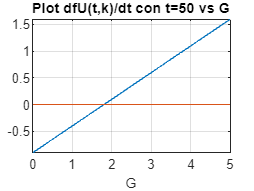

fplot(Udf, [0,5]);hold on;fplot(@(t) 0, [0,5]);title("Plot dfU(t,k)/dt con t=50 vs G");xlabel("G");hold off;grid on

root = fzero(Udf, 2)

root = 1.8000

U = @(t) root*interR(t)-C1*F(t)-C2*R(t)

U = function_handle with value:
    @(t)root*interR(t)-C1*F(t)-C2*R(t)


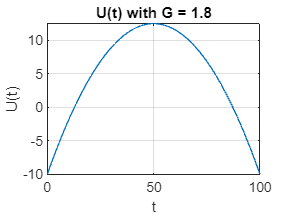

fplot(U, [a,b]);title("U(t) with G = 1.8");xlabel("t");ylabel("U(t)");grid on

[tOpt2, fObj2] = newtonRaphsonMinimo(U, 50)

tOpt2 = 50.0000

fObj2 = 12.5000

function [x, fx, i, min] = newtonRaphsonMinimo(f,x)
    %Parámetros iniciales
    max = 52;
    tol = sqrt(eps);
    i = 0;
    cond =  true;
    fs = sym(f);
    dfs = diff(fs);
    dfs2 = diff(dfs);
    df = matlabFunction(dfs);
    df2 = matlabFunction(dfs2);
    if nargin(df)<1
        error('Function has not second reivate')
    end
    if nargin(df2) < 1
        df2 = @(x) df2();
    end
    while cond
        xp = x;
        x = xp-df(xp)/df2(xp);
        cond = abs((x-xp)/x) > tol && i < max;
        i = i+1;
    end
    min = df2(x) > 0;  
    fx = f(x);
end